clearvars;
dir = 'results/optimization/results_4/'

dir = 'results/optimization/results_4/'

outdir = 'results/optimization_results/'

outdir = 'results/optimization_results/'

load([dir,'optimization_results.mat']);

totaln = length(optimization_combined);
n_account = fix(totaln/6);
n_bin = fix((1 / 3) * n_account);

% limits.pd_min = -0.2;   limits.pd_max = 0;
% limits.or_min = -0.2;   limits.or_max = 0.2;
% limits.ee_min = 0.8;    limits.ee_max = 0.4;
% limits.theta_min = 0;   limits.theta_max = 180;
% limits.off_min = 0;     limits.off_max = 180;
% limits.delay_min = -45; limits.delay_max = 0;

limits.pd_min = -0.2;   limits.pd_max = 0;
limits.or_min = -0.2;   limits.or_max = 0.2;
limits.ee_min = 0.8;    limits.ee_max = 1.4;
limits.theta_min = -20;   limits.theta_max = -5;
limits.off_min = 0;     limits.off_max = 180;
limits.delay_min = -50; limits.delay_max = 50;

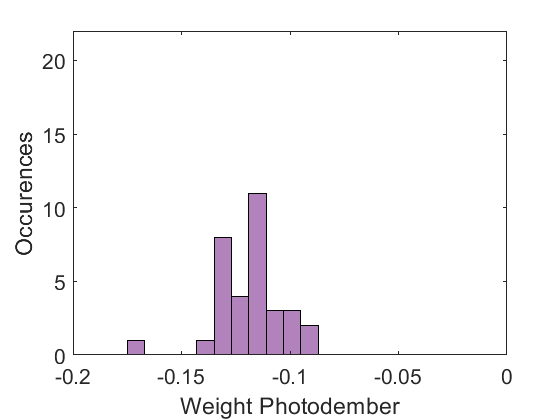

weight_pd = [optimization_combined(1:n_account).weight_pd];
H = histogram(weight_pd,n_bin,'FaceColor',	'#7E2F8E');
set(gca,'FontSize',16);
xlim([limits.pd_min limits.pd_max]);
ylim([0, 2 * n_bin]);
xlabel('Weight Photodember');
ylabel('Occurences');
exportgraphics(gca,[outdir,'pdweight.png'],'Resolution',300);

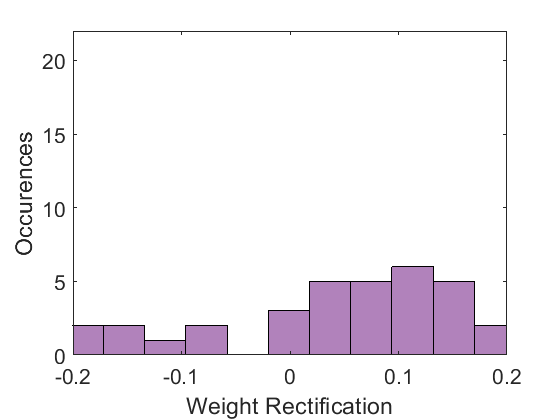

weight_or = [optimization_combined(1:n_account).weight_or];
H = histogram(weight_or,n_bin,'FaceColor','#7E2F8E');
set(gca,'FontSize',16);
xlim([ limits.or_min limits.or_max ]);
ylim([0, 2 * n_bin]);
xlabel('Weight Rectification');
ylabel('Occurences');
exportgraphics(gca,[outdir,'orweight.png'],'Resolution',300);

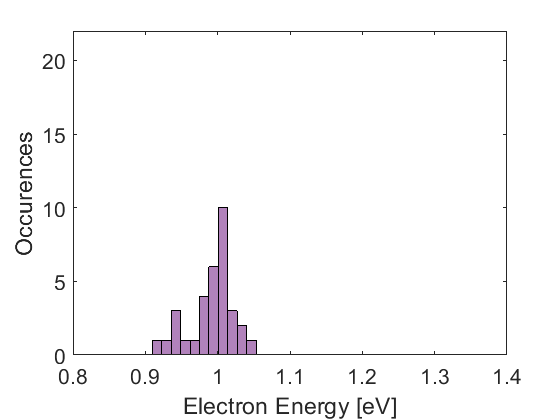

electron_energy = [optimization_combined(1:n_account).electron_tot_energy];
H = histogram(electron_energy,n_bin,'FaceColor','#7E2F8E');
set(gca,'FontSize',16);
xlim([limits.ee_min limits.ee_max ]);
ylim([0, 2 * n_bin]);
xlabel('Electron Energy [eV]');ylim([0, 2 * n_bin]);
ylabel('Occurences');
exportgraphics(gca,[outdir,'electronenergy.png'],'Resolution',300);

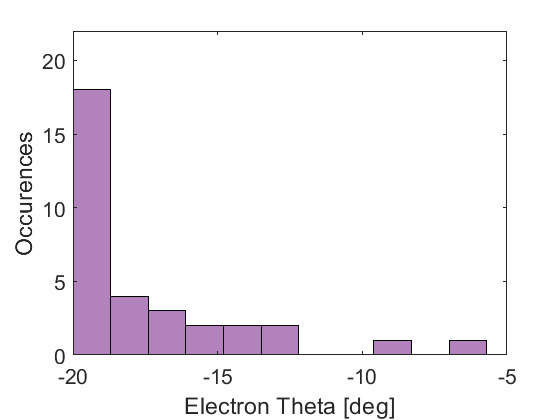

electron_theta = [optimization_combined(1:n_account).electron_theta_deg];
H = histogram(electron_theta,n_bin,'FaceColor','#7E2F8E');
set(gca,'FontSize',16);
xlim([ limits.theta_min limits.theta_max]);
ylim([0, 2 * n_bin]);
xlabel('Electron Theta [deg]');
ylabel('Occurences');
exportgraphics(gca,[outdir,'electronthetay.png'],'Resolution',300);

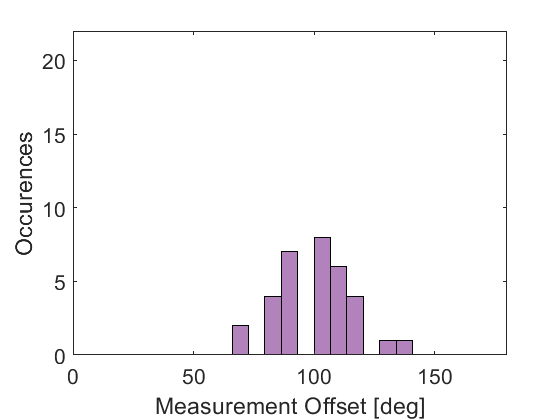

offset = [optimization_combined(1:n_account).offset];
H = histogram(offset,n_bin,'FaceColor','#7E2F8E');
set(gca,'FontSize',16);
xlim([limits.off_min limits.off_max ]);
ylim([0, 2 * n_bin]);
xlabel('Measurement Offset [deg]');
ylabel('Occurences');
exportgraphics(gca,[outdir,'offset.png'],'Resolution',300);

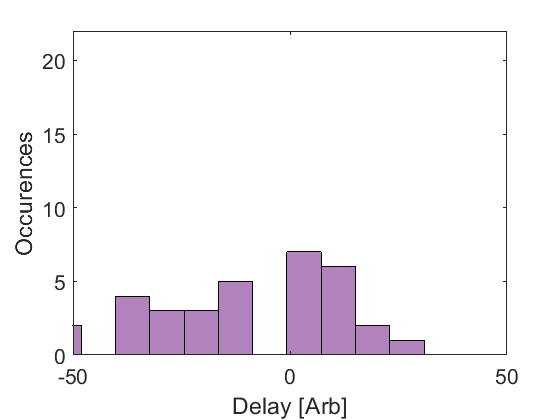

delay = [optimization_combined(1:n_account).delay];
H = histogram(delay,n_bin,'FaceColor','#7E2F8E');
set(gca,'FontSize',16);
xlim([limits.delay_min limits.delay_max ]);
ylim([0, 2 * n_bin]);
xlabel('Delay [Arb]');
ylabel('Occurences');
exportgraphics(gca,[outdir,'delay.png'],'Resolution',300);